## Prac 2

close all; clc; clear;

### Exercise 1

1. Initial conditions and function definition

syms x
x0 = 1; t0 = 0; tf=2; nPts = 100;
fx = -x;
fx_Anon = matlabFunction(fx);

2. Unique theoretical solution

% Define symbolic functions
syms t x(t)
% Define the ODE
EQN = diff(x,t) == -x

$$EQN(t) = \frac{\partial }{\partial t}x\left(t\right)=-x\left(t\right)$$

% Initial condition
cond = x(0) == 1;
% Solve the ODE
xtruesol = dsolve(EQN,cond)

$$xtruesol = {\mathrm{e}}^{-t}$$

%figure; fplot(xtruesol,[0,3]);

% Create a time vector ts between 0 to 3 and dt=0.01
dt = 2/(100-1); ts = 0:dt:2; 
% Evaluation de solution in ts
xs = double(subs(xtruesol,t,ts));
% Plot the different solutions
figure('Position', [1000, 1000, 800, 600]);
subplot(2,2,1)
plot(ts,xs); % Plot points (ts,xs)
hold on

3. Euler's method for solving the initial value problem.

% Implement our function 'MyEuler'
[t1,x1] = MyEuler(x0,t0,tf,nPts,fx_Anon)

t1 =          0    0.0202    0.0404    0.0606    0.0808    0.1010    0.1212    0.1414    0.1616    0.1818    0.2020    0.2222    0.2424    0.2626    0.2828    0.3030    0.3232    0.3434    0.3636    0.3838    0.4040    0.4242    0.4444    0.4646    0.4848    0.5051    0.5253    0.5455    0.5657    0.5859    0.6061    0.6263    0.6465    0.6667    0.6869    0.7071    0.7273    0.7475    0.7677    0.7879    0.8081    0.8283    0.8485    0.8687    0.8889    0.9091    0.9293    0.9495    0.9697    0.9899


x1 =     1.0000    0.9798    0.9600    0.9406    0.9216    0.9030    0.8847    0.8669    0.8494    0.8322    0.8154    0.7989    0.7828    0.7670    0.7515    0.7363    0.7214    0.7068    0.6926    0.6786    0.6649    0.6514    0.6383    0.6254    0.6127    0.6004    0.5882    0.5764    0.5647    0.5533    0.5421    0.5312    0.5204    0.5099    0.4996    0.4895    0.4796    0.4700    0.4605    0.4512    0.4420    0.4331    0.4244    0.4158    0.4074    0.3992    0.3911    0.3832    0.3755    0.3679


% Plot the results
plot(t1,x1)

4. Improved Euler's method for solving the initial value problem.

% Implement our function 'MyImprovedEuler'
[t2,x2] = MyImprovedEuler(x0,t0,tf,nPts,fx_Anon)

t2 =          0    0.0202    0.0404    0.0606    0.0808    0.1010    0.1212    0.1414    0.1616    0.1818    0.2020    0.2222    0.2424    0.2626    0.2828    0.3030    0.3232    0.3434    0.3636    0.3838    0.4040    0.4242    0.4444    0.4646    0.4848    0.5051    0.5253    0.5455    0.5657    0.5859    0.6061    0.6263    0.6465    0.6667    0.6869    0.7071    0.7273    0.7475    0.7677    0.7879    0.8081    0.8283    0.8485    0.8687    0.8889    0.9091    0.9293    0.9495    0.9697    0.9899


x2 =     1.0000    0.9800    0.9604    0.9412    0.9224    0.9039    0.8859    0.8681    0.8508    0.8338    0.8171    0.8007    0.7847    0.7690    0.7537    0.7386    0.7238    0.7093    0.6952    0.6813    0.6676    0.6543    0.6412    0.6284    0.6158    0.6035    0.5914    0.5796    0.5680    0.5567    0.5455    0.5346    0.5239    0.5134    0.5032    0.4931    0.4832    0.4736    0.4641    0.4548    0.4457    0.4368    0.4281    0.4195    0.4111    0.4029    0.3949    0.3870    0.3792    0.3716


% Plot the results
plot(t2,x2)

5. Runge-Kutta method for solving the initial value problem.

% Implement our function 'MyRungeKutta'
[t3,x3] = MyRungeKutta(x0,t0,tf,nPts,fx_Anon)

t3 =          0    0.0202    0.0404    0.0606    0.0808    0.1010    0.1212    0.1414    0.1616    0.1818    0.2020    0.2222    0.2424    0.2626    0.2828    0.3030    0.3232    0.3434    0.3636    0.3838    0.4040    0.4242    0.4444    0.4646    0.4848    0.5051    0.5253    0.5455    0.5657    0.5859    0.6061    0.6263    0.6465    0.6667    0.6869    0.7071    0.7273    0.7475    0.7677    0.7879    0.8081    0.8283    0.8485    0.8687    0.8889    0.9091    0.9293    0.9495    0.9697    0.9899


x3 =     1.0000    0.9800    0.9604    0.9412    0.9224    0.9039    0.8858    0.8681    0.8508    0.8338    0.8171    0.8007    0.7847    0.7690    0.7536    0.7386    0.7238    0.7093    0.6951    0.6812    0.6676    0.6543    0.6412    0.6284    0.6158    0.6035    0.5914    0.5796    0.5680    0.5566    0.5455    0.5346    0.5239    0.5134    0.5031    0.4931    0.4832    0.4736    0.4641    0.4548    0.4457    0.4368    0.4281    0.4195    0.4111    0.4029    0.3948    0.3869    0.3792    0.3716


% Plot the results
plot(t3,x3)

6. Plot the results of every method together.

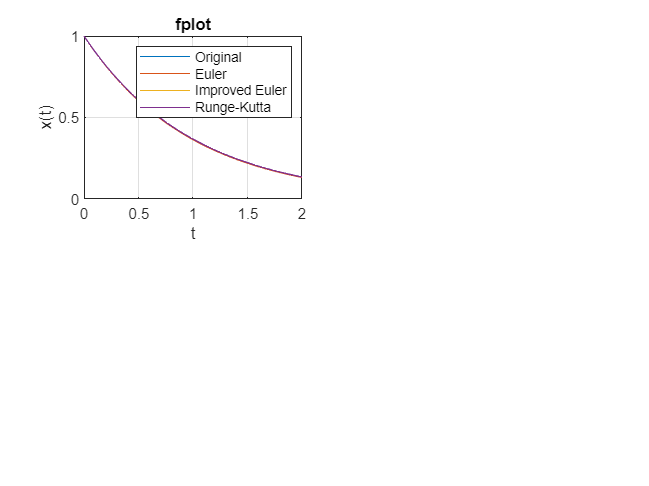

xlabel('t');ylabel('x(t)');grid on; title('fplot')
legend('Original', 'Euler', 'Improved Euler', 'Runge-Kutta')

7. Error computation

a) Euler error:

% Euler errorabs(exp((-t)) - sym(7/9))
Euler_error = abs(x1-xs)

Euler_error =          0    0.0002    0.0004    0.0006    0.0008    0.0009    0.0011    0.0013    0.0014    0.0016    0.0017    0.0018    0.0019    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0028    0.0029    0.0030    0.0030    0.0031    0.0032    0.0032    0.0033    0.0033    0.0034    0.0034    0.0035    0.0035    0.0035    0.0036    0.0036    0.0036    0.0036    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037


% Plot the results
figure('Position', [100, 100, 800, 600]);
subplot(2,1,2)
plot(t1,log(Euler_error))
hold on

b) Improved Eurler error

% Improved Euler error
impEuler_error = abs(x2-xs)

impEuler_error = 	1.0e+-4 *

         0    0.0137    0.0268    0.0394    0.0515    0.0631    0.0742    0.0848    0.0950    0.1047    0.1140    0.1229    0.1314    0.1395    0.1472    0.1546    0.1616    0.1682    0.1746    0.1806    0.1863    0.1917    0.1968    0.2016    0.2062    0.2105    0.2145    0.2183    0.2219    0.2252    0.2283    0.2312    0.2339    0.2364    0.2387    0.2408    0.2427    0.2445    0.2460    0.2475    0.2487    0.2499    0.2508    0.2517    0.2524    0.2529    0.2534    0.2537    0.2539    0.2541


% Plot the results
plot(t2,log(impEuler_error))

c) Runge-Kutta error

% Runge-Kutta error
rg_error = abs(x2-xs)

rg_error = 	1.0e+-4 *

         0    0.0137    0.0268    0.0394    0.0515    0.0631    0.0742    0.0848    0.0950    0.1047    0.1140    0.1229    0.1314    0.1395    0.1472    0.1546    0.1616    0.1682    0.1746    0.1806    0.1863    0.1917    0.1968    0.2016    0.2062    0.2105    0.2145    0.2183    0.2219    0.2252    0.2283    0.2312    0.2339    0.2364    0.2387    0.2408    0.2427    0.2445    0.2460    0.2475    0.2487    0.2499    0.2508    0.2517    0.2524    0.2529    0.2534    0.2537    0.2539    0.2541


% Plot the results
plot(t3,log(rg_error))

Labels for the plotting

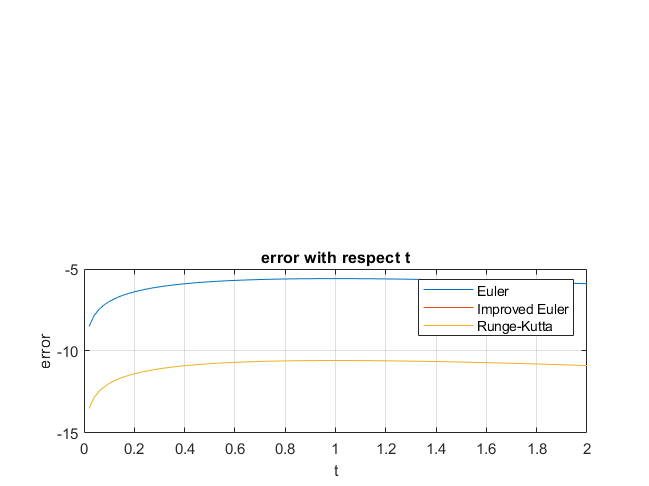

xlabel('t');ylabel('error');grid on; title('error with respect t')
legend('Euler', 'Improved Euler', 'Runge-Kutta')